clear
clc
cls

useToolBox = 1; % ★　

## 固有空間の作成

### 学習工程（3.1.1）

width_ = 100; % ★　image width
height_ = 100;% ★　image height
M = width_ * height_; % resolution

dTheta = 10; % ★　回転ステップ for all data, deg
theta = 0:dTheta:360

theta =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300   310   320   330   340   350   360



trainData.dTheta = 30; % ★　回転ステップ for training, deg

dataDir = "data/20250502/renamed/" % ★　

dataDir = "data/20250502/renamed/"


% deg, attitude angle for training
trainData.angle = 0:trainData.dTheta:360

trainData = フィールドをもつ struct:
    dTheta: 30
     angle: [0 30 60 90 120 150 180 210 240 270 300 330 360]


trainData.indx = 0:trainData.dTheta/dTheta:length(theta);
trainData.nImage = length(trainData.angle);
trainData.data = zeros(M, trainData.nImage);
for i = 1:trainData.nImage
    fName = sprintf("image_%03d.jpeg", trainData.indx(i));
    fName = strcat(dataDir, fName)
    img = imread(fName);
    gsImage = im2gray(imresize(img, [height_ width_]));
    trainData.data(:, i) = reshape(gsImage, M, 1);
end

fName = "data/20250502/renamed/image_000.jpeg"

fName = "data/20250502/renamed/image_003.jpeg"

fName = "data/20250502/renamed/image_006.jpeg"

fName = "data/20250502/renamed/image_009.jpeg"

fName = "data/20250502/renamed/image_012.jpeg"

fName = "data/20250502/renamed/image_015.jpeg"

fName = "data/20250502/renamed/image_018.jpeg"

fName = "data/20250502/renamed/image_021.jpeg"

fName = "data/20250502/renamed/image_024.jpeg"

fName = "data/20250502/renamed/image_027.jpeg"

fName = "data/20250502/renamed/image_030.jpeg"

fName = "data/20250502/renamed/image_033.jpeg"

fName = "data/20250502/renamed/image_036.jpeg"


c = mean(trainData.data, 2);
if useToolBox
    [tmpE, ~, ~] = pca(double(trainData.data)');
else %遅い
    Xbar = trainData.data - c;
    Q = 1 / trainData.nImage * Xbar * Xbar';
    [tmpE, D] = eig(Q);
end 

### learning data projection

k = 8; % ★　用いる特徴空間の次元
E = tmpE(:, 1:k);
trainData.g = zeros(k, trainData.nImage);

% projection
for i = 1:trainData.nImage
    trainData.g(:,i) = (E' * (trainData.data(:, i) - c))';
end

### 認識工程（3.1.2）

dThetaTest = 10; % ★ 回転ステップ for test, deg
testData.indx = 0:dThetaTest/dTheta:length(theta)

testData = フィールドをもつ struct:
    indx: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37]


testData.angle = 0:dThetaTest:theta(end)

testData = フィールドをもつ struct:
     indx: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37]
    angle: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240 250 260 270 280 290 300 310 320 330 340 350 360]


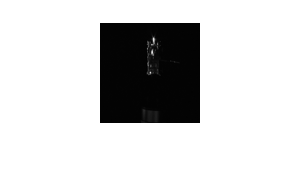

% もしくは手動で設定する．
% testData.indx = [9]; % ★ 
% testData.angle = [270];  % ★ 

testData.nImage = length(testData.angle);
testData.data = zeros(M, testData.nImage);
for i = 1:testData.nImage
    fName = sprintf("image_%03d.jpeg", testData.indx(i));
    fName = strcat(dataDir, fName);
    img = imread(fName);
    gsImage = im2gray(imresize(img, [height_ width_]));
    imshow(gsImage);
    testData.data(:, i) = reshape(gsImage, M, 1);

    testData.z(:,i) = E' * (testData.data(:,i) - c); % projected test data
end

### attitude determination for each test data

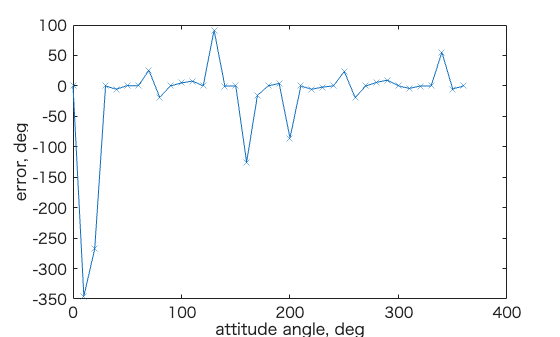

for i = 1:testData.nImage
    dis = vecnorm(testData.z(:,i) - trainData.g, 2, 1); % n x nLearn    

    [minVal, indx] = min(dis);
    w1 = minVal;
    theta1 = trainData.angle(indx);

    % weighted average
    if indx == 1
        indx2 = indx + 1;
    elseif indx == length(trainData.g)
        indx2 = indx - 1;
    else  
        [~, offset] = min([dis(indx - 1), dis(indx + 1)]);
        indx2 = indx + (2 * offset - 3);  % offset=1→-1, offset=2→+1となる．
    end
    w2 = dis(indx2);
    theta2 = trainData.angle(indx2);

    % estimated attitude angle, deg
    thetaHat(i) = (w2 * theta1 + w1 * theta2)/(w1 + w2);
end

figure
plot(testData.angle, testData.angle - thetaHat, '-x')
xlabel('attitude angle, deg'), ylabel('error, deg')